# tRGS_f_prod Test

In this notebook, we're testing an implementation of tensor randomized factoreized Gauss Seidel.

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

close all
l = 5;
p = 7;
n = 10;
m = 20;
k = 5;
% Generate tensor factors
U = randn(m,n,l);
V = randn(n,k,l);

% Generate tensors
A = tprod(U,V); % m,k,l
X_true = randn(k,p,l);

%generate consistent measurements
B = tprod(A,X_true); % m,p,l

Now, let's test the implementation of tRGS.

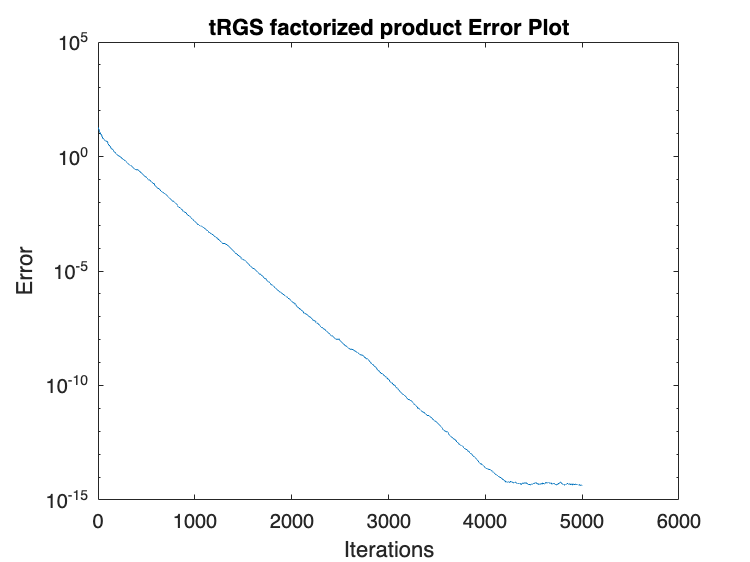

%run some iterations of tRK
num_its = 5000;
[~,its_X,its_Z] = tRGS_f_prod(U,V,B,randn(k,p,l),num_its);

%record errors
errs = [];
for j = 1:num_its+1
    est = its_X{j} - X_true;
    errs = [errs,norm(est(:))];
end

%plot errors vs iterations
semilogy(errs)
hold on
title('tRGS factorized product Error Plot')
xlabel('Iterations') 
ylabel('Error') 

And it appears this implementation is working!